clc
clear all

## 数据导入

fnameA = "D:\temp\work\1.轮廓法结果\410rs\20241104\1.txt";
fnameB = "D:\temp\work\1.轮廓法结果\410rs\20241104\2.txt";
ImpDataA = sandata(fnameA);
ImpDataB = sandata(fnameB);
% dlmwrite('D:\temp\work\401\pointdata\251\251-3\B.txt',ImpDataB,'delimiter','\t','precision','%.6f')
x0 = ImpDataB(:,1); 
x0 = -x0;
ImpDataB(:,1) = x0;
ImpData = [ImpDataA;ImpDataB];
% [ImpData(:,2),ImpData(:,3)] = Re(ImpData(:,2),ImpData(:,3));
% [ImpData(:,1),ImpData(:,3)] = Re(ImpData(:,1),ImpData(:,3));
% ImpData = sandata(fnameA);
bd = [-7.5,0;7.5,0;7.5,-70;-7.5,-70;-7.5,0];

## 单面

% fnameA = "F:\02技术资料\401轮廓法\738-1\7381-A.txt";
% ImpData = sandata(fnameA);
% % [ImpData(:,2),ImpData(:,3)] = Re(ImpData(:,2),ImpData(:,3));
% % [ImpData(:,1),ImpData(:,3)] = Re(ImpData(:,1),ImpData(:,3));
% % ImpData = sandata(fnameA);
% bd = [-7.5,0;7.5,0;7.5,-70;-7.5,-70;-7.5,0];

## 前处理

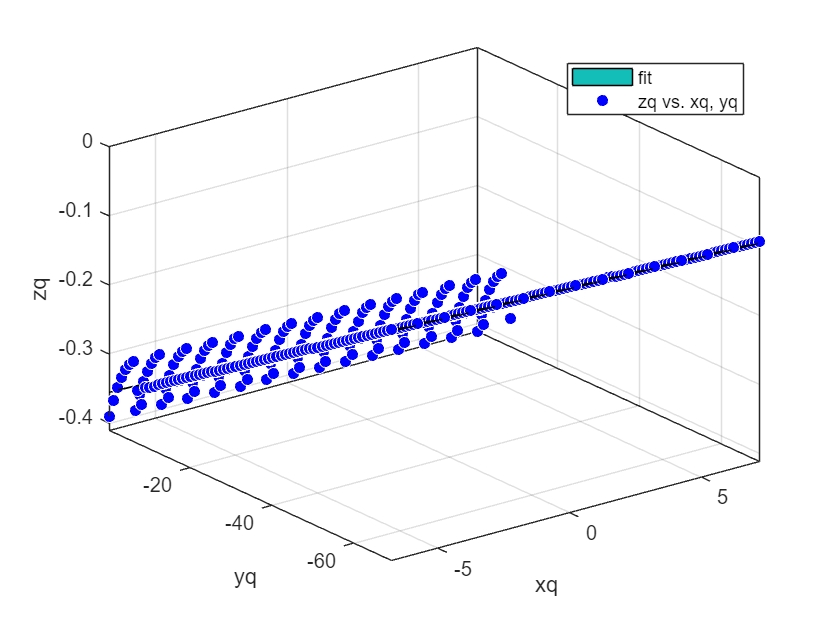

%网格化 
d = 1;%网格大小
ws = 15;
newdata = DataMesh(ImpData,d,bd);
point = newdata.point;
in = newdata.in;
xm = newdata.xm;
ym = newdata.ym;
zvmCi = newdata.zvmCi;
%平滑
zvmCi = smoothdata(zvmCi,'sgolay',ws);
%沿行方向平滑
zvmCi = smoothdata(zvmCi,2,"sgolay",ws);
zq = zvmCi(in);
xq = xm(in);
yq = ym(in);
% 拟合
n = 4;%拟合方程次数
[f  gof] = createFit(xq, yq, -zq, n);

P = coeffvalues(f);%多项式系数向量
s = dispf(P,n,n);
disp(s)

-0.3666 + -0.004472*Y + -4.5136e-05*Y*Y + -1.1683e-06*Y*Y*Y + -8.7907e-09*Y*Y*Y*Y + -0.0013468*X + -1.2658e-06*X*Y + 1.8303e-08*X*Y*Y + 8.1552e-11*X*Y*Y*Y + 4.4828e-18*X*X + -1.2885e-19*X*X*Y + -2.8774e-21*X*X*Y*Y + 5.915e-20*X*X*X + -1.1975e-20*X*X*X*Y + -1.0982e-19*X*X*X*X 


disp(gof)

           sse: 0.0943
       rsquare: 0.9868
           dfe: 1035
    adjrsquare: 0.9867
          rmse: 0.0095



## 单面拟合

% ii = xq > 0;
% X1 = xq(ii); Y1 = yq(ii); Z1 = zq(ii);
% n = 4;%拟合方程次数
% [f  gof] = createFit(X1, Y1, Z1, n);
% P = coeffvalues(f);%多项式系数向量
% s = dispf(P,n,n);
% disp(s)
% disp(gof)
% 
% % X2 = xq(~ii); Y2 = yq(~ii); Z2 = zq(~ii);
% X2 = -X1; Y2 = Y1; Z2 = Z1;
% n = 4;%拟合方程次数
% [f  gof] = createFit(X2, Y2, Z2, n);
% P = coeffvalues(f);%多项式系数向量
% s = dispf(P,n,n);
% disp(s)
% disp(gof)